# ECE 1395 Project:

## Chess Evaluator

**Names:** Benjamin Bryla, Gabriel Yeniceri

clear; clc

## Thresholds

%Positin is classified as equal if within
IsEqual=75; %Position is equal if magnitude is inbetween +# and -#

%If checkmate exists, force evaluation to be
CheckmateThreshold=1000; %  [M-2] -> [-1000]

%Used as seed for RNG
RNG=123;


# Data Preprocessing:

#### Loading Data:

%Read filename and input into array
filename = "input\dataset_eval.csv";

%Options for getting CSV file read correct
options=detectImportOptions(filename);
options=setvartype(options,["Var2","Var4"],"string"); %Force strings, Eval: M1 does not give NaN value anymore
options.Delimiter = ',';
options.VariableNamingRule = 'preserve';

Data = readtable(filename, options);

#### Split data into Position and Evaluation

FEN = Data{:,2};
Eval = Data{:,4};

Column 1 and 3 are unneccessary. Column 1 is the game #, this will not influence training in any way. Column 3 is best move, the scope of the project will no longer contain the best move, instead it only contains evaluation. 

Cleanup

clearvars options filename Data

## Evaluation Pre-Process:

This part of the pre-processing will deal with the evaluation output. 

- If there is checkmate on board (denoted by M # or M- #) the evaluation is going to be set to some variable defined above. 

- The evaluation of each position is given relative to who's turn it is, + is winning for whoever's turn it is. The evaluation will be changed to absolute relative to white. + is winning for white no matter who's turn it is.

- The evaluation is also going to be turned into classes based on some threshold defined above, -1 black winning, 0 is within threshold, 1 white winning. Adding 2 to every column will change it to 1 is black winning, 2 is equal, 3 is white winning. 

%Modify mate on boards
is_M = contains(Eval(:),'M'); %If Mate is on Board
is_EvalMinus = ~contains(Eval(:),'-'); %If evaluation contains a - 

IsMate=((is_EvalMinus-0.5)*2).*is_M*CheckmateThreshold; %Mating Threat new evals
IsMateShort=IsMate(IsMate~=0);

%Change eval from Relative based on turn, to Absolute based on White
is_WhiteTurn = contains(FEN(:),'w'); %If is White's Turn

EvalAbsolute=(is_WhiteTurn-0.5)*2;

%Change Checkmate in # to Checkmate Threshold
Eval(is_M)=IsMateShort; 
%Change Relative eval to Absolute Eval
Eval=str2double(Eval);
Eval=Eval.*EvalAbsolute;

%Create Discrete Evaluation
function EvalDiscrete=DiscreteEval(Eval,Threshold)
Greater= Eval>=Threshold;
Less= Eval<=-Threshold;

EvalDiscrete=Greater-Less;
end

EvalDiscrete=DiscreteEval(Eval,IsEqual);


Cleanup

clearvars is_M is_M is_EvalMinus IsMate IsMateShort EvalAbsolute CheckmateThreshold Greater Less

## Bitboard Pre-Process:

Converts FEN notation to Bitboard Representation

%Splits bitboard into Board, and Extras
SplitFEN=split(FEN); %Index 1 is Board, Index 2-6 is extra information
%Board Split
Board=split(SplitFEN(:,1),'/');

BoardExtra=SplitFEN(:,2:end);

#### Written:

At this point we have the board, m x 8 string, each column represents a chess board column. BoardExtra is split up into 5 columns, turn, Castling rights, Enpassant rights, half move clock, full move number. 

cleanup

clearvars SplitFEN

## Bitboard Creation

FEN to Piece Board function. Takes in the board split from above

%Create a Piece Board
function PieceBoard=FEN2Piece(Board)
    PieceBoard=zeros(1,8*8);
    L=strlength(Board);
    for dataNum=1:height(Board) %For every data set
        CurrBoard = Board(dataNum,:);
        rowIndex=1;
        for column=1:8 %For every column of chess board
            CurrRow = CurrBoard(column);
            for row=1:L(dataNum,column) %For the rows of the chess board
                charRow=CurrRow{1}(row);
                if isstrprop(charRow, 'digit') %If number is found add it's value to index do not update the piece board
                    rowIndex = rowIndex + str2double(charRow);
                else %If character is found
                    PieceBoard(dataNum,rowIndex)=charRow; %If char is found, set char
                    rowIndex=rowIndex+1; %Increment

timeElapsed = 31.5996

                end

Time to convert 341019 FEN to bitboard: 31.59956


            end
        end
    end
end

Piece to Bit Board function

function BitBoard=Piece2Bit(Piece)
%List of pieces
pieceList='pbnrqkPBNRQK';
for m=1:height(Piece)
    BitBoard=false(height(Piece),8*8*12);
    for squareIndex=1:64 %Check every square for if it contains a piece
        for pieceIndex=1:12
            if pieceList(pieceIndex)==Piece(squareIndex)

index: 3651


                BitIndex=squareIndex+64*pieceIndex-64; %Calculate index of the bitboard square
                BitBoard(BitIndex)=1; %And set to true

Show the current board state


            end

r~bq~rk~
~p~~~ppp
p~~~pn~~
~~~p~~~~
~~~~~~~~
~P~BPN~~
~PP~~PPP
R~~QK~~R


        end
    end
end
end

p


   0   0   0   0   0   0   0   0
   0   1   0   0   0   1   1   1
   1   0   0   0   1   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



b


   0   0   1   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



n


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



r


   1   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



q


   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



k


   0   0   0   0   0   0   1   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



P


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   1   0   0   1   0   0   0
   0   1   1   0   0   1   1   1
   0   0   0   0   0   0   0   0



B


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



N


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   1   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0



R


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   1   0   0   0   0   0   0   1



Q


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   0



K


   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0
   0   0   0   0   1   0   0   0



Converts the Board representation into Bitboards

%Number of data points to use
m=height(Board);
%m=5000;

%Setup Empty Arrays
Data=Board(1:m,:);
PieceBoard=zeros(height(Data),8*8);
BitBoard=false(height(Data),8*8*12);

%Convert to piece board
tic
for i=1:m
    PieceBoard(i,:)=FEN2Piece(Board(i,:));
    BitBoard(i,:)=Piece2Bit(PieceBoard(i,:));
end
timeElapsed=toc
fprintf("Time to convert %d FEN to bitboard: %0.5f\n",m,timeElapsed)

%Convert to Char
PieceBoard=char(PieceBoard);
%Fill in Empty
PieceBoard(PieceBoard==0)='~';

Cleanup

clearvars Data timeElapsed i Board

## FEN Conversion Verification

Testing: Check current board state based on index

index=3651;
disp("index: "+index)
ShowBoard=reshape(PieceBoard(index,:),8,8)'; %Convert from Piece Board into 8x8
disp("Show the current board state")
disp(ShowBoard)

pieceList='pbnrqkPBNRQK';
for i=0:11 %Each Piece
    disp(pieceList(i+1))
    disp(reshape(BitBoard(index,64*i+1:64*i+64),8,8)') %Convert from Bit Board into 12x8x8
end

Cleanup

clearvars index ShowBoard disp i

Example at Index 285; Comparing Chess.com vs Matlab; The current board state in an array that represents the same boardstate as chess.com's FEN analysis. 

Data Set: Eval = -358: EvalDiscrete = -1 (black winning). 

Chess.com Evaluation -3.47, -1 (black winning) , depth 17, 3 seconds. This 100x scaling in the data set is used to removing the decimal. 

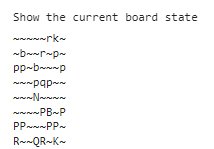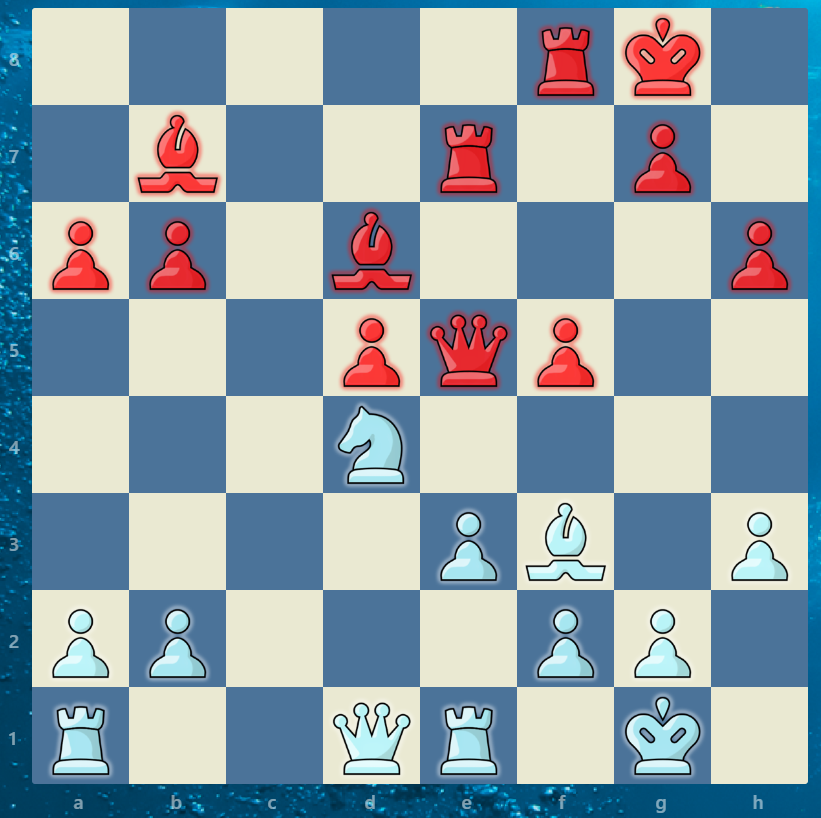

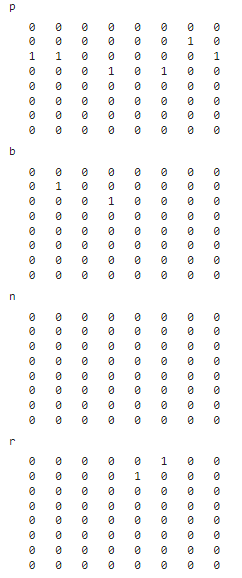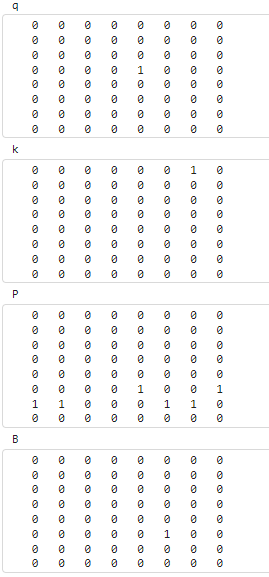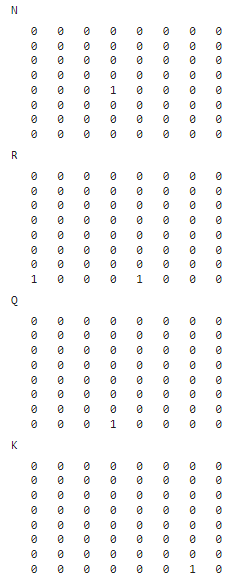

When looking at the bit board, it aligns with the location of pieces for FEN notation. Lowercase = Black pieces. Uppercase = White Pieces. The position is aligned with the standard chess board position. K is White's King, in both the bit board, piece board, and chess.com it is shown in the G1 square. p is Black's Pawns, the structure is the same in all 3 representations. n is Black's Knights, the bitboard is all 0's because black does not have a knight. 

## FEN Extra Data

FEN notation has 5 additional bits of information that need to be dealt with. 

It is split up into the BoardExtra variable, they were all separated prevously by the space demileter

Column 1: Who's turn it is. b=black, w=white

Will be represented by a 1=white, 0=black

is_WhiteTurn; %Already created when coverting from relative to absolute evaluation. 

Column 2: KQkq, Castling legality, K=White king side castle, Q=White Queen Side Caste. kq are same but for black;

can_Castle=zeros(height(BoardExtra),1);
%Can white castle King/Queen side
can_Castle(:,1)=contains(BoardExtra(:,2),"K");
can_Castle(:,2)=contains(BoardExtra(:,2),"Q");
%Can black castle King/Queen side
can_Castle(:,3)=contains(BoardExtra(:,2),"k");
can_Castle(:,4)=contains(BoardExtra(:,2),"q");

Column 3: En-Passant Rights, if a piece can enpassant, this is the square it can go to. 

1=Can EnPassant, 0=Cannot. This is unlikely to have many data points (417, ~0.12% total positions, 5175 games total, 417 positions even have it as an option), in addition it is not a critical portion of an evaluation, a true/false value should suffice for our use. Any non '-' value will be set to 1 for can en-passant. 

is_EnPassant=BoardExtra(:,3)~='-';

Column 4: Half-Move Clock. Counts up by 1 every half move (white OR black moves), resets to 0 every time there is a, capture, or pawn move. This is from the 50 move rule in chess where if neither side captures, or makes a pawn move the game is a draw;

Convert to Double: 

HalfMove=str2double(BoardExtra(:,4));

Column 5: Full Move Counter. after white AND Black has moves, ticks up by 1. How many moves the game has been;

Convert to Double: 

FullMove=str2double(BoardExtra(:,5));

Full Bitmap

BitBoardFull=[BitBoard,is_WhiteTurn,can_Castle,is_EnPassant,HalfMove,FullMove];

Here we have the full BitBoard

Index References:

1-768 = Bitboard of piece locations, 12x8x8 in 'pbnrqkPBNRQK' piece order

769: Who's turn it is. 1=White, 0=Black

770-773: Castling Rights. White: King Queen side, Black: King Queen side, 1=Yes Castle

774: Is En-Passant Legal, 1=Yes

775: Half Move Clock

776: Full Move Counter

cleanup

clearvars can_Castle BoardExtra FullMove HalfMove is_EnPassant m 

# Linear Regression Implementation

Ben is Implementing this portion

Paremeters

alpha=0.01;
num_iters=200;

Split into Test & Training data set

%Set RNG & Split
rng(RNG)

Training Time: 33.9

SplitCutoff=height(Eval)*0.1; % 10% is Testing
Split=randperm(height(Eval));

%Define Test
X_Test=BitBoardFull(Split(1:SplitCutoff),:);
y_Test=Eval(Split(1:SplitCutoff),:);
%Define Validate
X_Train=BitBoardFull(Split(SplitCutoff+1:end),:);
y_Train=Eval(Split(SplitCutoff+1:end),:);

Train a model

rng(RNG)

tic;
model=fitlm(X_Train,y_Train,'linear'); %Linear Regression Model
time=toc;
fprintf("Training Time: %0.1f",time)

Calculate accuracy

Also check with Normal Equation

function theta = normalEqn(X,y)
    %Normal Equation

Normal Accuracy: 67.8%


    theta = ((pinv(X'*X))*X')*y;
end

Normaltheta = normalEqn(X_Train,y_Train);
y_predict=X_Test * Normaltheta;

%Convert into classes
y_predictDiscrete=DiscreteEval(y_predict,IsEqual);
y_TestDiscrete=DiscreteEval(y_Test,IsEqual);

Model Accuracy: 67.8%


%Accuracy
accuracy= mean(y_predictDiscrete==y_TestDiscrete);
fprintf("Normal Accuracy: %0.1f%%\n",accuracy*100)

y_predict=predict(model,X_Test);

White's Turn Weight: 1.3986



%Convert into classes
y_predictDiscrete=DiscreteEval(y_predict,IsEqual);
y_TestDiscrete=DiscreteEval(y_Test,IsEqual);
%Accuracy

Error between Normal and Linear Model


accuracy= mean(y_predictDiscrete==y_TestDiscrete);
fprintf("Model Accuracy: %0.1f%%\n",accuracy*100)

Evaluate outcome

Check the weight each piece has on each square. 

p


Average Piece Weight: -1.1103


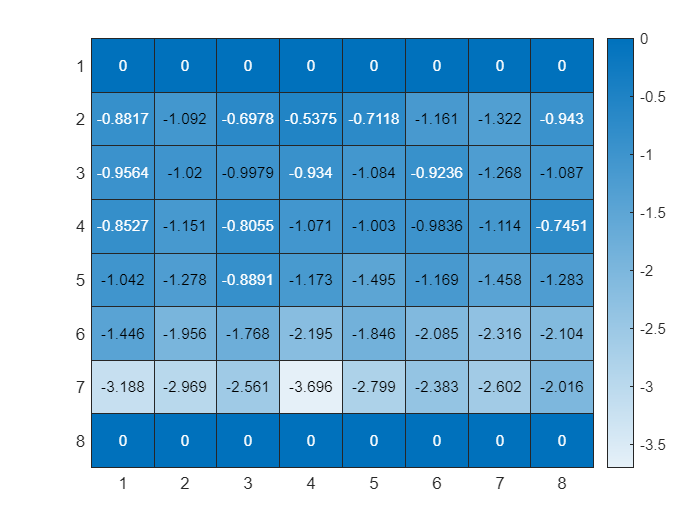

b


Average Piece Weight: -2.7649


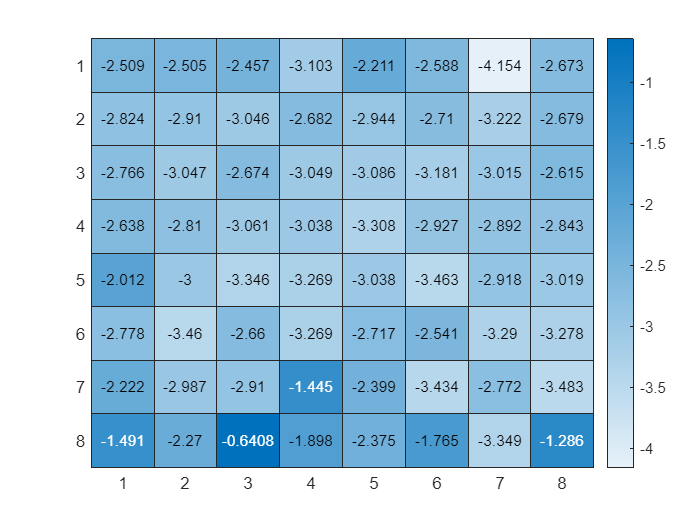

n


Average Piece Weight: -2.5502


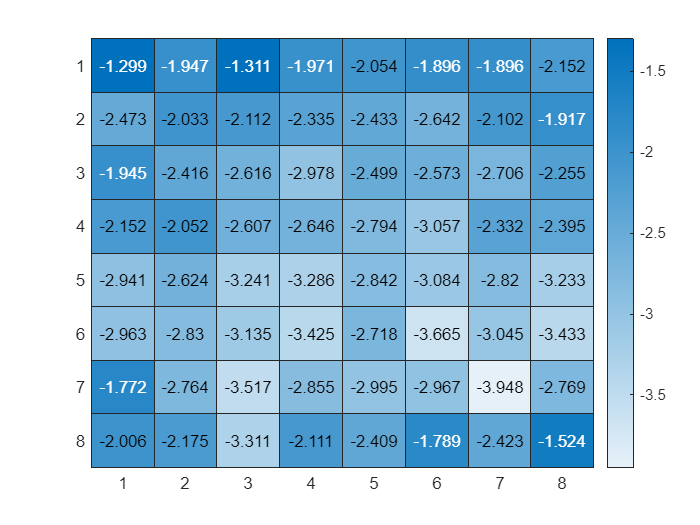

r


Average Piece Weight: -4.0591


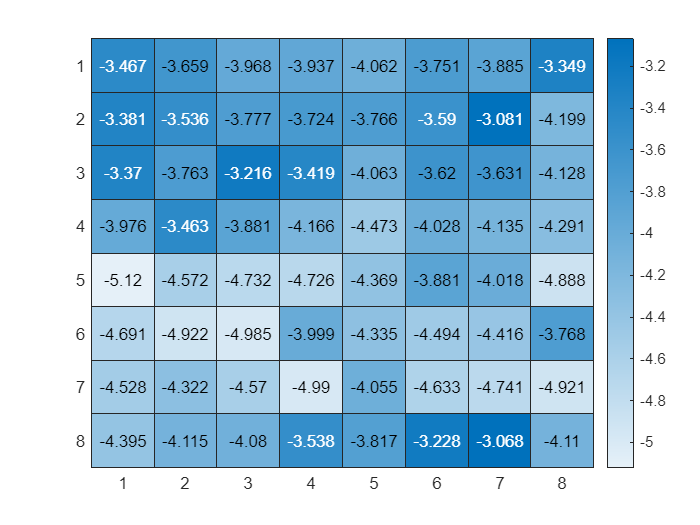

q


Average Piece Weight: -6.2439


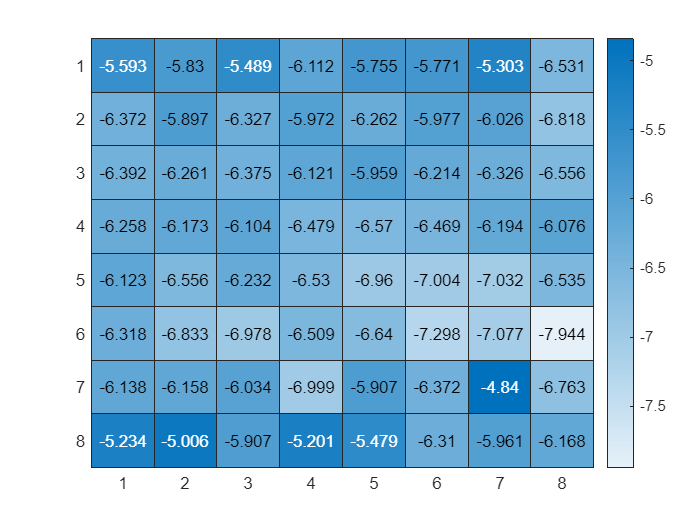

k


Average Piece Weight: 2.2693


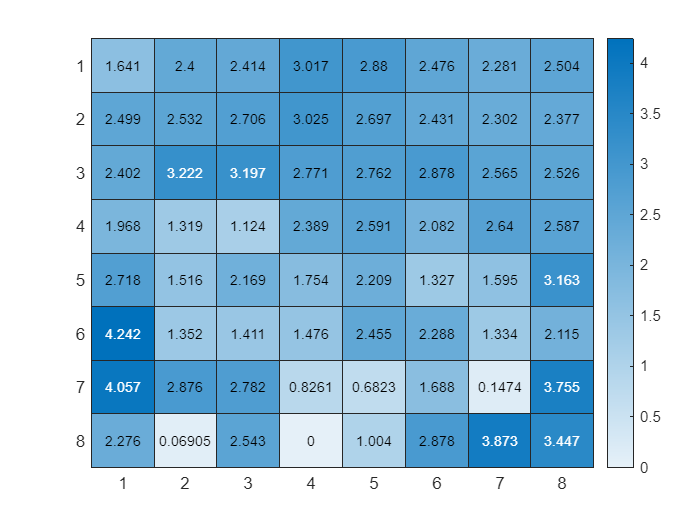

P


Average Piece Weight: 1.0323


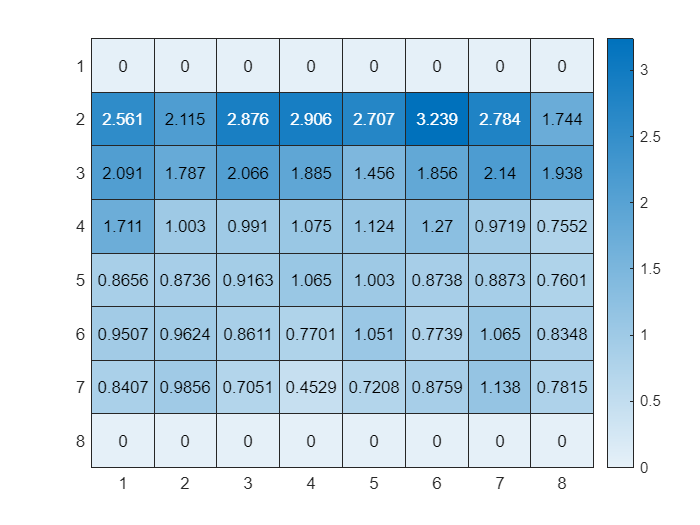

B


Average Piece Weight: 2.8916


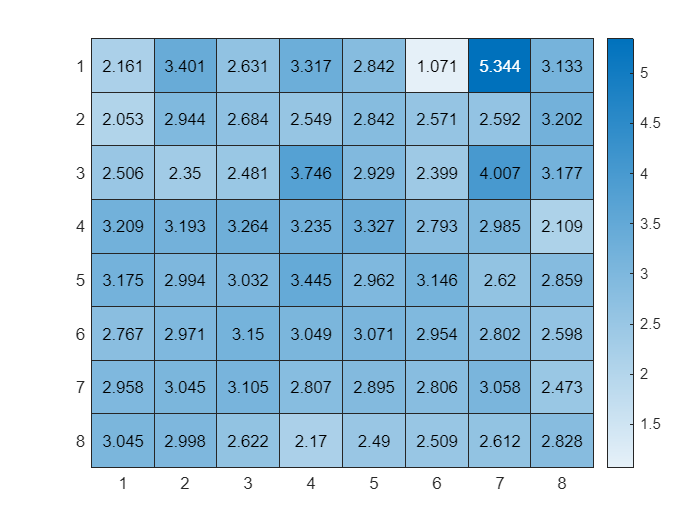

N


Average Piece Weight: 2.5067


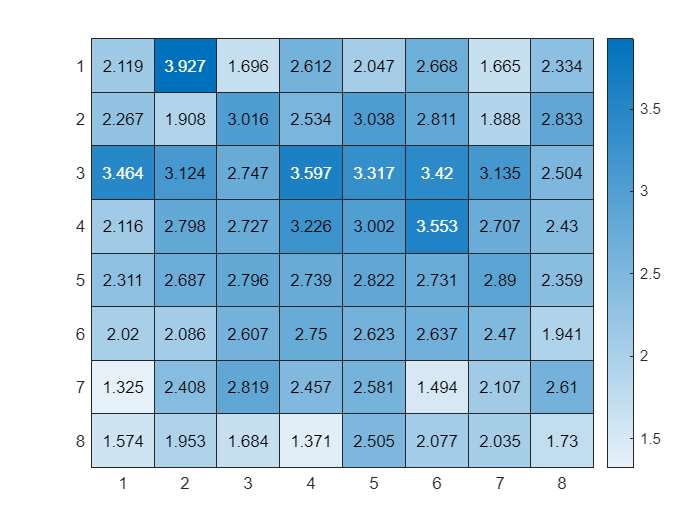

R


Average Piece Weight: 4.0397


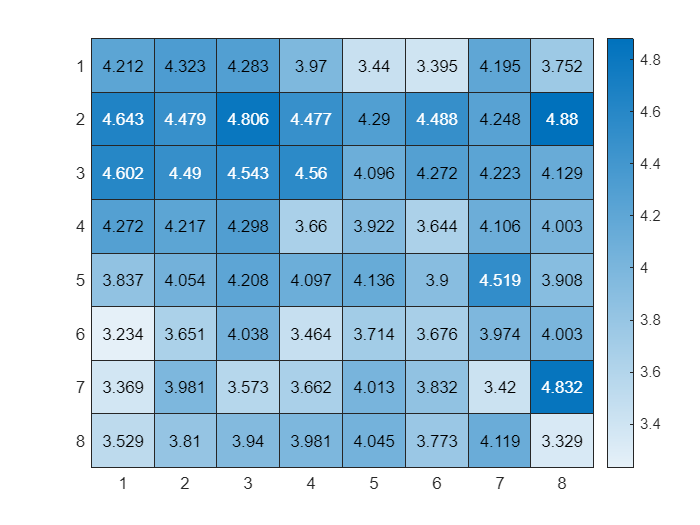

Q


Average Piece Weight: 6.2058


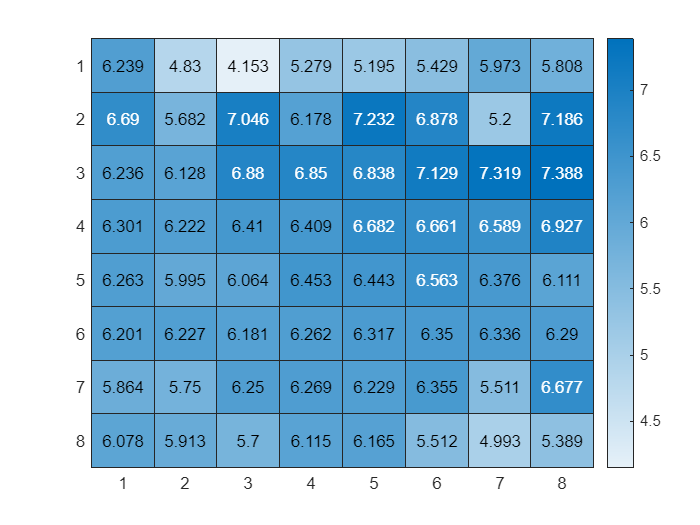

K


Average Piece Weight: -0.92769


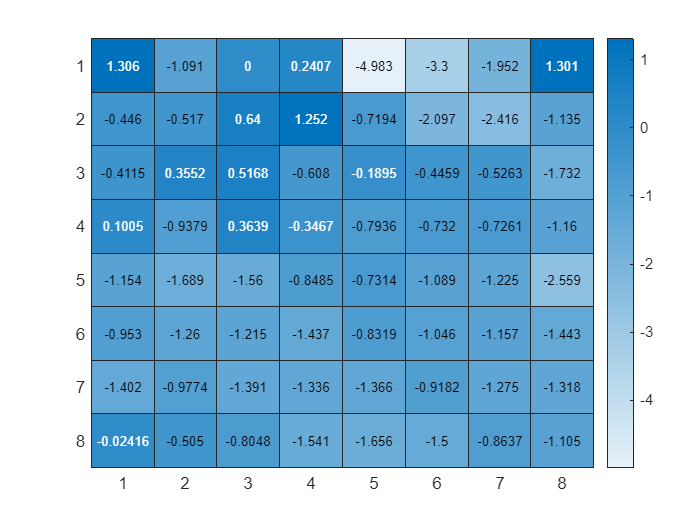

BitThetas=table2array(model.Coefficients);

disp("White's Turn Weight: "+BitThetas(770,1)/100)
BitThetas=BitThetas(2:769,1);

NormalPieces=Normaltheta(1:768);

disp("Error between Normal and Linear Model")

Error=(NormalPieces-BitThetas)./NormalPieces;


pieceList='pbnrqkPBNRQK';
for i=0:11 %Each Piece
    disp(pieceList(i+1))
    disp("Average Piece Weight: "+mean(BitThetas(64*i+1:64*i+64,1)/100))
    figure
    %disp(reshape(BitThetas(64*i+1:64*i+64,1),8,8)'/100) %Convert from Bit Board into 12x8x8
    heatmap(reshape(BitThetas(64*i+1:64*i+64,1),8,8)'/100)
end

Maybe check correlation with a Piece Square Table

Any positive values means that White is winning, Negative values means Black's winning

Looking at the average weights of each piece, the ratio between them roughly aligns with the standard value of pieces.

While the model has higher accuracy for the equal threshold being higher, the thresholds for a game is around 50 for roughly equal, 100 for a slight advantage, 150 for a clear advantage, 200 and above is a decisive advantage. 

From what I can tell the pawn weights are biased taking only the mean since as pawns get further and closer to promotion the weight increases to around 1/2 the value of a queen, 1 square from promotion. This extra weight as pawns are more advanced is expected because a pawn that threatens promotion is an advantage for whoever has the pawn. The top and bottom rows are all 0's for pawns because they cannot be on that square in the first place. 

The weights also accurately represent how although the standard convention of the knight being the same value as the knight, in practice the bishop has a slight advantage, ranging from 3 to 3.25, this difference can be seen in the weights of the two pieces. 

The weight for the rook is around 1.55x that of the knight for white, this is around the expected 5/3, 1.66x from the standard convention, this value of pieces is still within a reasonable range. 

The weight for the queen is far less than I expected, with only being 1.5x that of the rook, or 2.4x that of the knight. these values should be 1.8x and 3x respectively. I predict this is due to the queen's power comes from how it can go around the board and threaten tactics while a linear regression is only able to evaluate the value of pieces

The evaluation of the king is biased towards endgames where the king is an active piece, in a middle game or early game it is nearly impossible for a king to be on the other side of the board, and in a majority of positions the king will be in the starting position or castled, the weights for king that is not within 1 square of being castled, or starting square is likely to not be in the training set many times outside of an endgame. 

White's Turn: 1.39, Having it be a player's turn is generaly known as a 0.3 advantage, around 1/3 of a pawn. In the linear regression model the turn advantage was much higher than expected. This may be due to in the training set where tactics exist and if it is missed then there is a major change in the rating, this would put a much higher priority onto who's turn it is. 

Observing the normal equation's result it is approximately the same as the linear regression model for all except , this means that the linear regression is likely to have worked. 

Looking at the error bettween Normal Equation and Linear Regression, all pieces except the king have an error of 10^-10 or less for IsEqual=75

# CNN Implementation

rng(RNG)
%reshapes input to 8*8*12
N = size(BitBoard,1);
X_CNN = reshape(BitBoard',8,8,12,N);
%Converts classification
Y_CNN = categorical(EvalDiscrete + 2);

%Splits data
idx = randperm(N);
numTest = round(0.10*N);
numVal = round(0.10*N);
numTrain = N - numTest - numVal;
trainIdx = idx(1:numTrain);
valIdx = idx(numTrain+1:numTrain+numVal);
testIdx = idx(numTrain+numVal+1:end);
XTrain = X_CNN(:,:,:,trainIdx);
YTrain = Y_CNN(trainIdx);
XVal = X_CNN(:,:,:,valIdx);
YVal = Y_CNN(valIdx);
XTest = X_CNN(:,:,:,testIdx);
YTest = Y_CNN(testIdx);
%CNN
layers = [
    imageInputLayer([8,8,12],"Normalization","none","Name","input")
    convolution2dLayer(3,32,"Padding","same","Name","conv1")
    batchNormalizationLayer("Name","bn1")
    reluLayer("Name","relu1")
    convolution2dLayer(3,64,"Padding","same","Name","conv2")
    batchNormalizationLayer("Name","bn2")
    reluLayer("Name","relu2")
    fullyConnectedLayer(128,"Name","fc1")
    reluLayer("Name","relu3")
    dropoutLayer(0.3,"Name","drop1")
    fullyConnectedLayer(3,"Name","fc_out")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")
];
%Swap these two if you do not have a GPU
%cut training time from 40-50 minutes to almost 6 minutes
%options = trainingOptions("adam","MaxEpochs",15,"MiniBatchSize",256,"InitialLearnRate",1e-3,"Shuffle","every-epoch","ValidationData",{XVal,YVal},"ValidationFrequency",50,"Verbose",true,"Plots","training-progress");
options = trainingOptions("adam","ExecutionEnvironment","gpu","MaxEpochs",15,"MiniBatchSize",256,"InitialLearnRate",1e-3,"Shuffle","every-epoch","ValidationData",{XVal,YVal},"ValidationFrequency",50,"Verbose",true);
tic;
net = trainNetwork(XTrain,YTrain,layers,options);

|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       29.69% |       35.19% |       1.6399 |       3.9162 |          0.0010 |
|       1 |          50 |       00:00:01 |       57.42% |       55.65% |       0.9454 |       0.9166 |          0.0010 |
|       1 |         100 |       00:00:02 |       57.42% |       58.01% |       0.8782 |       0.8836 |          0.0010 |
|       1 |         150 |       00:00:03 |       65.62% |       61.93% |       0.8352 |       0.8419 |          0.0010 |
|       1 |         200 |       

cnnTrainTime = toc;

# Evaluate Output

fprintf("CNN Training Time: %0.1f s\n",cnnTrainTime);

CNN Training Time: 278.0 s


YPred = classify(net,XTest);
cnnAccuracy = mean(YPred == YTest);
fprintf("CNN Accuracy: %0.3f%%\n",cnnAccuracy*100);

CNN Accuracy: 82.083%


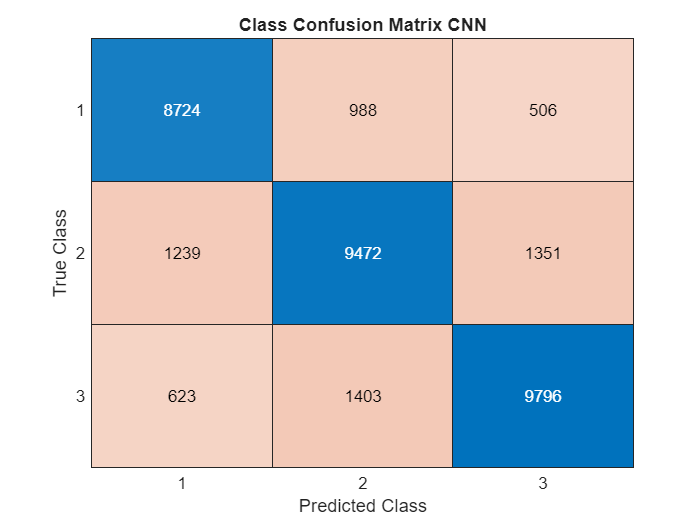

%Matrix comparing the 3 classes
figure;
confusionchart(YTest,YPred);
title("Class Confusion Matrix CNN");

%Compare predicted classes
disp("First 40 Predicted Vs Actual")

First 40 Predicted Vs Actual


disp([double(YPred(1:40)) double(YTest(1:40))])

     1     1
     2     2
     1     3
     1     1
     1     1
     3     3
     3     3
     3     2
     2     2
     3     3
     1     1
     1     1
     1     1
     2     3
     1     1
     2     2
     3     3
     2     3
     1     1
     1     1
     1     1
     3     3
     3     3
     1     2
     2     3
     2     3
     2     2
     3     3
     1     2
     3     3
     3     2
     3     3
     2     2
     1     1
     2     2
     2     2
     2     2
     2     2
     1     3
     3     3



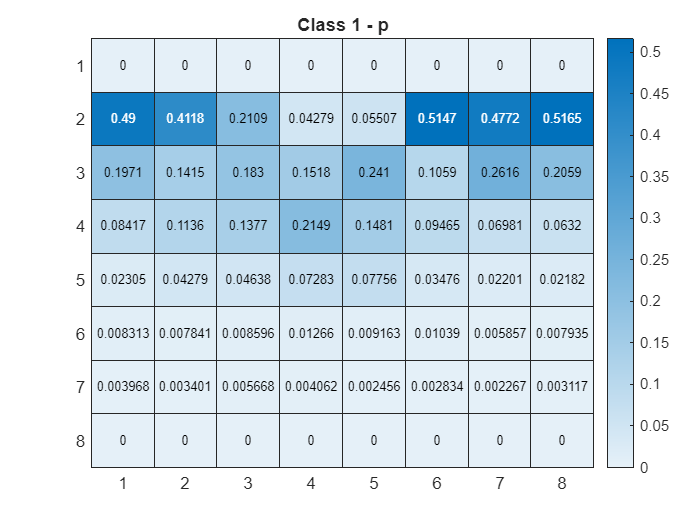

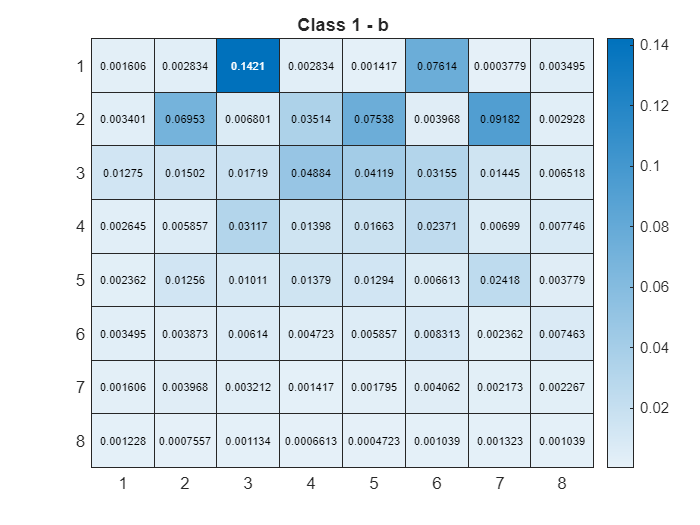

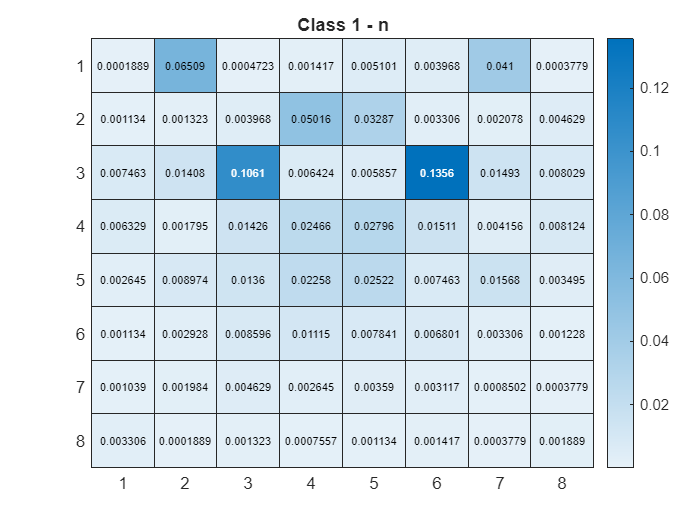

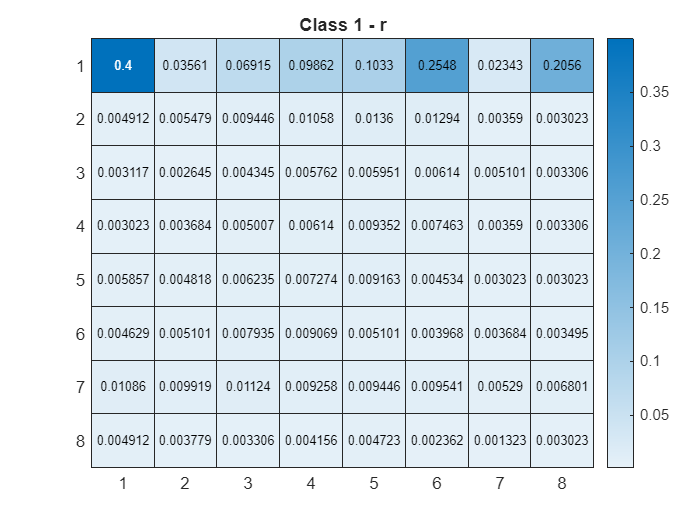

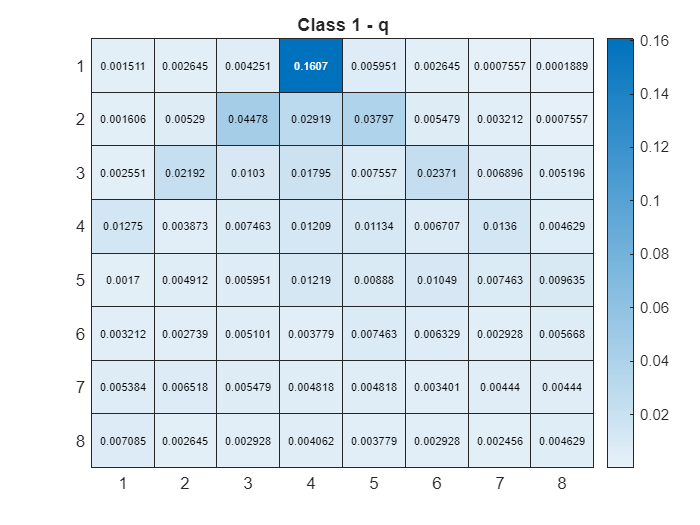

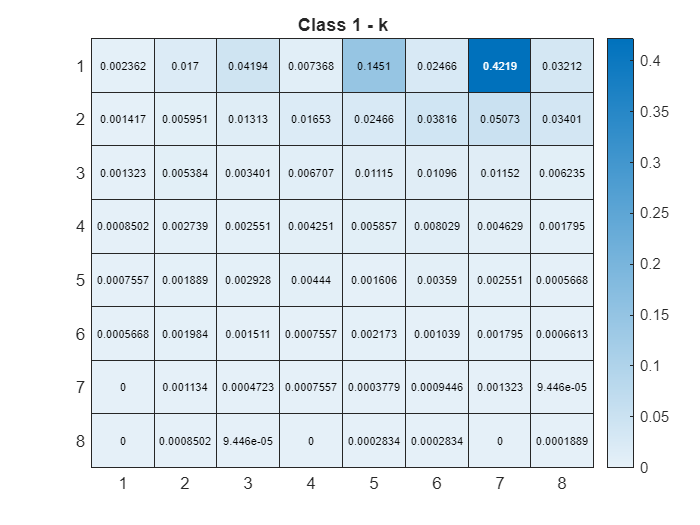

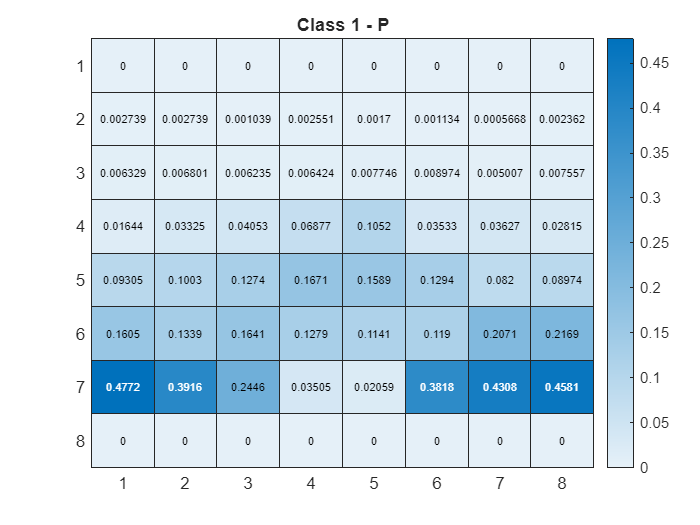

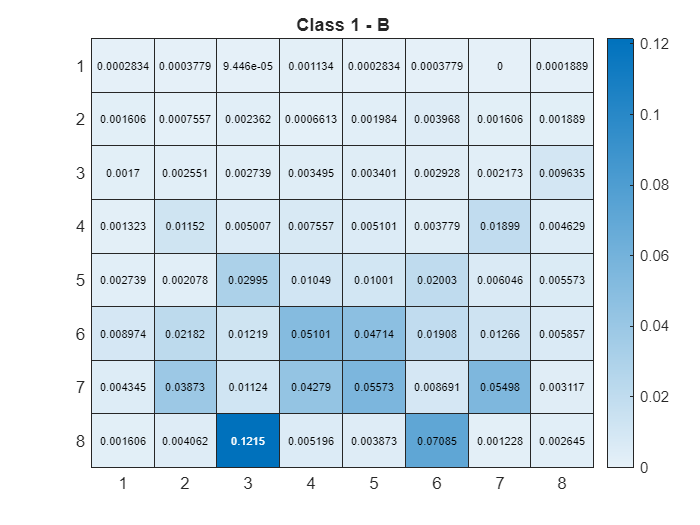

pieceList='pbnrqkPBNRQK';
YPred_num = double(YPred);
for c = 1:3
    idx = YPred_num==c;
    if ~any(idx), continue, end
    avgBoard = mean(XTest(:,:,:,idx),4); % 8x8x12
    for i = 1:12
        figure
        heatmap(avgBoard(:,:,i)')
        title("Class "+c+" - "+pieceList(i))
    end
end

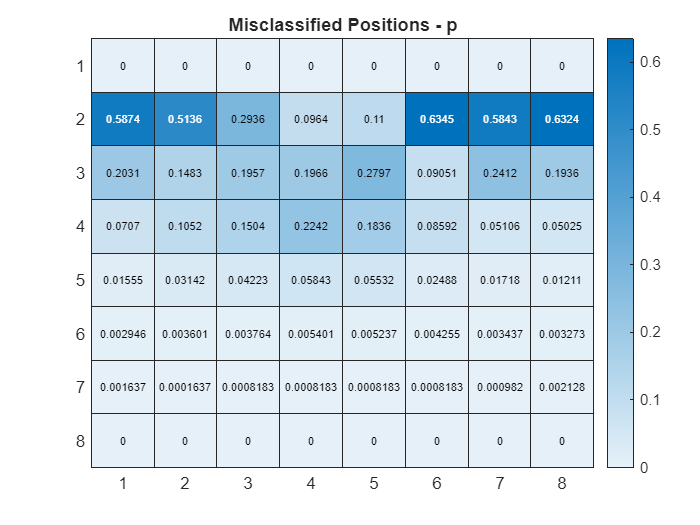

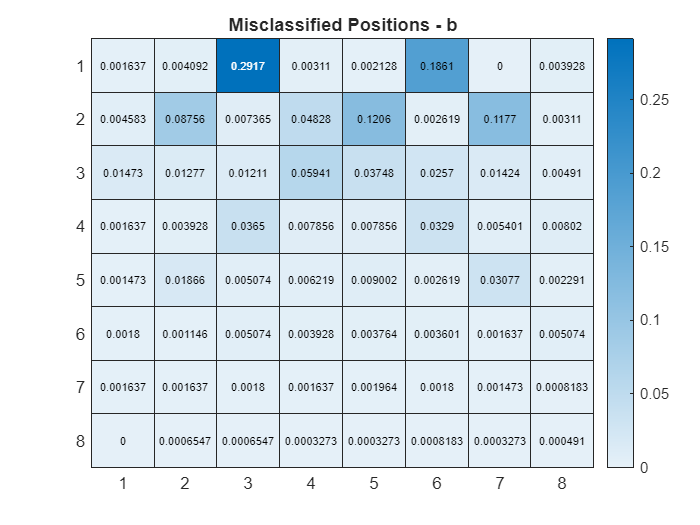

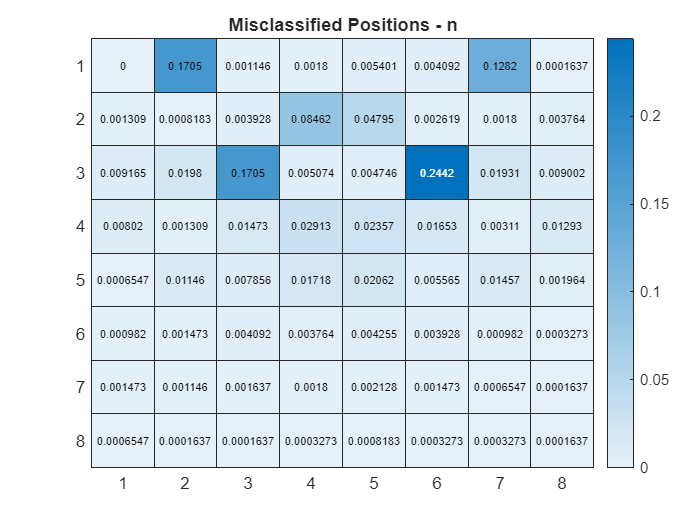

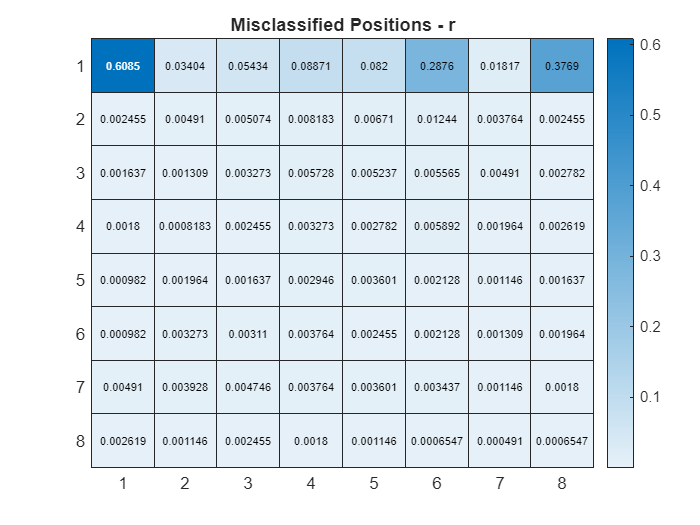

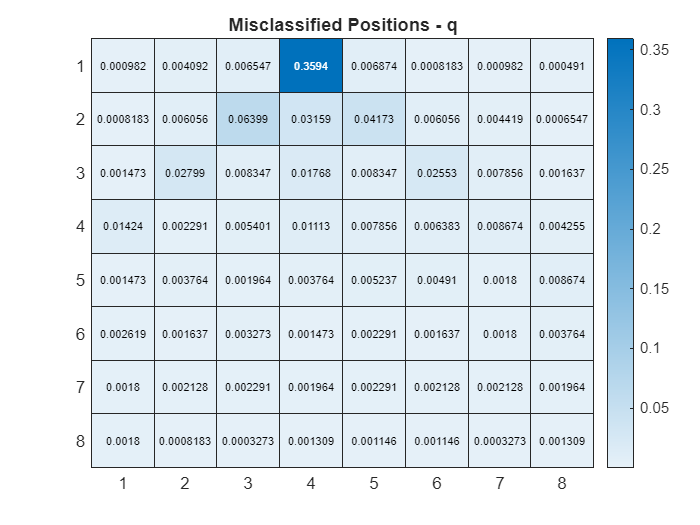

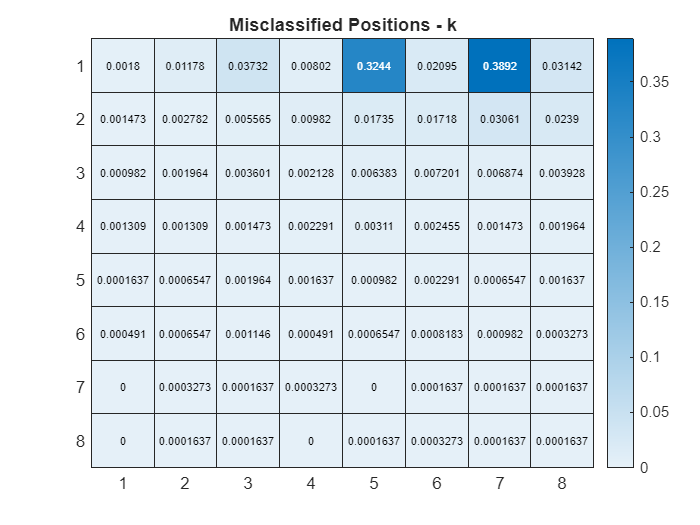

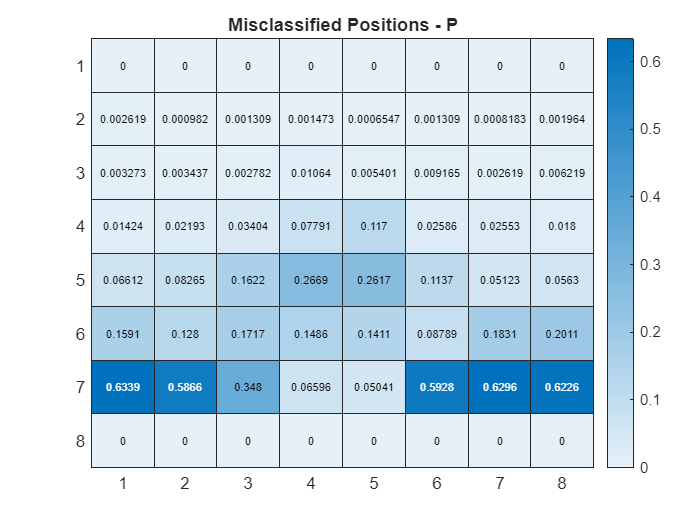

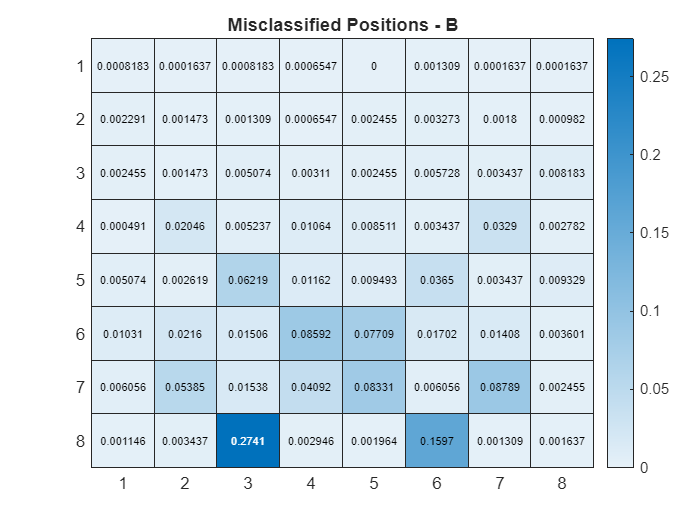

wrongIdx = find(YPred ~= YTest);
avgWrong = mean(XTest(:,:,:,wrongIdx),4);
for i = 0:11
    figure
    heatmap(avgWrong(:,:,i+1)')
    title("Misclassified Positions - "+pieceList(i+1))
end

# Evaluation